# Alkaline Membrane Electrolyser Impedance computation

## Setup model

jsonstruct_material = parseBattmoJson('Electrolyser/Parameters/alkalineElectrolyser.json');
jsonstruct_geometry = parseBattmoJson('Electrolyser/Parameters/electrolysergeometry1d.json');

jsonstruct = mergeJsonStructs({jsonstruct_material, ...
                               jsonstruct_geometry});

inputparams = ElectrolyserInputParams(jsonstruct);
inputparams = setupElectrolyserGridFromJson(inputparams, jsonstruct);

## Setup Impedance solver

We use a given current. The steady state is computed at setup.

options = [];
options.stateInitialization.initializationSetup = 'given current';
options.stateInitialization.computeSteadyState  = true;
options.stateInitialization.I = -3*ampere/(centi*meter)^2;

impsolv = ElectrolyserImpedanceSolver(inputparams, options);

Solving timestep 01/15:          -> 112 Seconds, 500 Milliseconds
Solving timestep 02/15: 112 Seconds, 500 Milliseconds -> 225 Seconds
Solving timestep 03/15: 225 Seconds -> 450 Seconds
Solving timestep 04/15: 450 Seconds -> 900 Seconds
Solving timestep 05/15: 900 Seconds -> 1800 Seconds
Solving timestep 06/15: 1800 Seconds -> 1 Hour
Solving timestep 07/15: 1 Hour   -> 2 Hours
Solving timestep 08/15: 2 Hours  -> 3 Hours
Solving timestep 09/15: 3 Hours  -> 4 Hours
Solving timestep 10/15: 4 Hours  -> 5 Hours
Solving timestep 11/15: 5 Hours  -> 6 Hours
Solving timestep 12/15: 6 Hours  -> 7 Hours
Solving timestep 13/15: 7 Hours  -> 8 Hours
Solving timestep 14/15: 8 Hours  -> 9 Hours
Solving timestep 15/15: 9 Hours  -> 10 Hours
*** Simulation complete. Solved 15 control steps in 15 Seconds, 534 Milliseconds ***


## Compute the impedance for a range of frequencies

omegas = linspace(-4, 2, 30);
omegas = 10.^omegas;
Z = impsolv.computeImpedance(omegas);

## Plots of the results

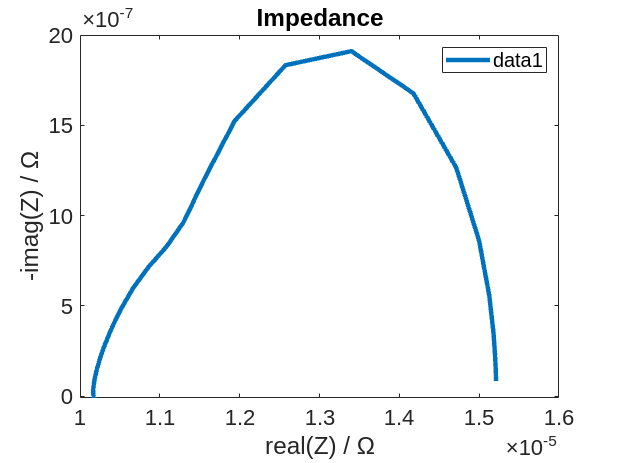

set(0, 'defaultlinelinewidth', 3);
figure
plot(real(Z), -imag(Z));
xlabel('real(Z) / Ω')
ylabel('-imag(Z) / Ω')
legend show
title('Impedance')